# Module 6: Image generation

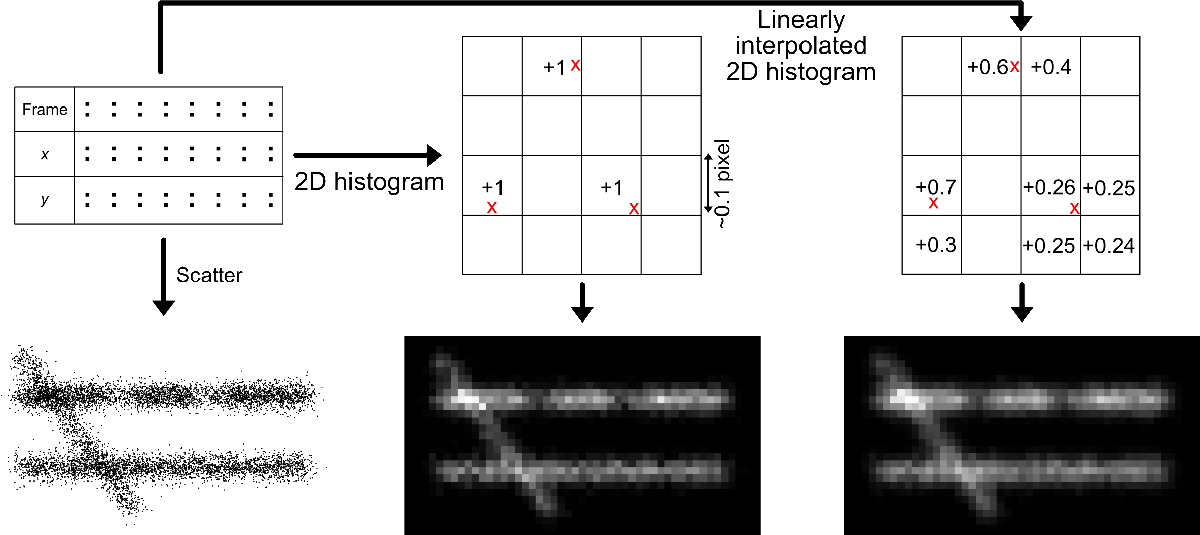

For structural SMLM data, image generation is a key concept to analyse the localization data. However, creating images from a list of zero-dimensional points is not trivial. Here we explore two commonly-used methods for the generation of images from SMLM data.

## Variable initialisation

% We load the data.
% data = commonFunctions.readTXTRapidSTORM('localization_file.txt');
data = commonFunctions.readTXTRapidSTORM('vimentin_BC2.txt');
% We determine the pixel size for the image generation. Here we set it up to 10 nm.
pixel_recon_dim = 15;

% We find the minimum X and Y values in our dataset. They will be used to shift 
% all data points to the left or up.
min_x = floor(min(data(:,2)));
min_y = floor(min(data(:,3)));

data(:,2) = data(:,2)-min_x;
data(:,3) = data(:,3)-min_y;

We explain two methods for image generation: 'simple' data binning with an additional optional convolution, and linear interpolation between data bins.

## Image generation by binning the data and convolution

The first method we explore is 'simple' binning of data. For this, a histogram with bin sizes that are smaller than the original pixels (normally ~10-15x smaller than original pixels) is filled based on the SMLM localizations. This is possibly convoluted with pseudo-Gaussian kernels to improve visibility.

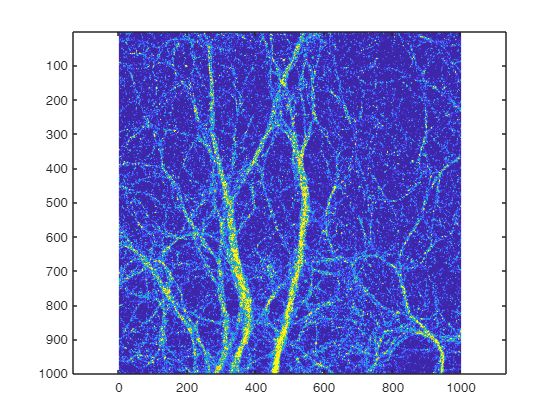

% The data are binned in two-dimensional histogram in X and Y dimensions.
% First the number of bins are specified in x and y based on the
% reconstruction size
numberBins = [ceil(max(data(:,2))/pixel_recon_dim), ceil(max(data(:,3))/pixel_recon_dim)];

%And the binning itself is done via the histcounts2 function.
histogram_original = histcounts2(data(:,2),data(:,3),numberBins);
%And the binning itself is done via the histcounts2 function.
binim = histcounts2(data(:,2),data(:,3),numberBins,...
    'XBinLimits',[0, numberBins(1)*pixel_recon_dim],...
    'YBinLimits',[0, numberBins(2)*pixel_recon_dim]);


% Convolution kernels are two dimensional arrays (here 3x3 and 5x5)
% by which we will possibly convolve the two-dimensional histogram later.
kernel_3x3 = [0 1 0;
    1 2 1;
    0 1 0];
kernel_5x5 = [0 0 1 0 0;
    0 1 2 1 0;
    1 2 3 2 1;
    0 1 2 1 0;
    0 0 1 0 0];

%The convolution is performed via the 'conv' method in the imfilter
%function
histogram_convolved = imfilter(histogram_original,kernel_3x3,'conv');

%Lastly, we visualise the image
%Opening the figure
figure()
%Plotting the image
imagesc(histogram_convolved);
%Setting reasonable colour limits
caxis([0 prctile(histogram_convolved(:),99)])
%Making the axis equal so it's not stretched
axis equal

## Image generation by linear interpolation

In this method, each datapoint is assigned to a single pixel, but the intensity of the event is distributed to up to three neighboring pixels (2x2) based on the subpixel localization.

In most extreme cases: 1) assuming the event is perfectly at the center of the pixel- the entire intensity will be assigned to this pixel; 2) the event is on the edge of the two pixels- it will equally share the intensity between these two pixels; 3) the event is at the corner of four pixels- the intensity will be shared between these four pixels equally.

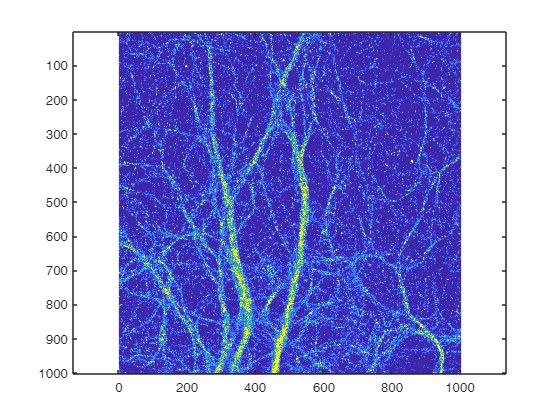

%First, an empty two-dimensional array is allocated.
% It will be populated with datapoints and finally will be used for
% the image reconstruction. Its dimensions are adjusted to the
% maximum X and Y coordinate values in the dataset divided by the
% pixel dimensions
% We need to add the value of 2: +1 because matlab starts indexing at
% 1, and +1 because we might want to look to the left/up of it (i.e.
% going to 0-index, which is illegal in matlab)
hist_linearinterp = zeros(ceil(max(data(:,2))/pixel_recon_dim)+2,...
    ceil(max(data(:,3))/pixel_recon_dim)+2);

% In this for loop each datapoint is assigned to four pixels
% (and in very exceptional cases to a single pixel if it is
% positioned at the center of the reconstruction iamge pixel)
% in the image reconstruction.
for i = 1:size(data,1)
    % Based on X and Y coordinates we determine the pixel position via the
    % floor function
    % We need to add 2 for the same reason as above
    coord_x = floor(data(i,2) / pixel_recon_dim)+2;
    coord_y = floor(data(i,3) / pixel_recon_dim)+2;

    % ... and also we determine the subpixel pisition of the event.
    % We subtract the halved pixel dimension value from X and Y subpixel
    % position in order to determine how the event is oriented with respect
    % to the pixel center. This value will be used  for the intensity
    % distribution and finding neighboring pixels which will receive a
    % fraction of this intensity as well
    position_x = mod(data(i,2),pixel_recon_dim) - pixel_recon_dim/2;
    position_y = mod(data(i,3),pixel_recon_dim) - pixel_recon_dim/2;
    
    % we calculate the 'pixel-intensity' which is used for the linear interpolation
    x_int = (-abs(position_x)/pixel_recon_dim + 1);
    y_int = (-abs(position_y)/pixel_recon_dim + 1);

    % Finally we distribute even intensities to pixels. 
    % The original pixel is at coord_x and coord_y values
    hist_linearinterp(coord_x, coord_y) = hist_linearinterp(coord_x, coord_y)+x_int*y_int;

    % The horizontal neighbor pixel is on the right (or left) side of the 
    % original pixel, assuming the datapoint is on the right (or left) 
    % half of the original pixel.
    if position_x > 0
        hist_linearinterp(coord_x+1, coord_y) = hist_linearinterp(coord_x+1, coord_y)+(1-x_int)*y_int;
    else
        hist_linearinterp(coord_x-1, coord_y) = hist_linearinterp(coord_x-1, coord_y)+(1-x_int)*y_int;
    end

    % Similarly we find a vertical neighbor in up & down dimension.
    if position_y > 0
        hist_linearinterp(coord_x, coord_y+1) = hist_linearinterp(coord_x, coord_y+1)+x_int*(1-y_int);
    else
        hist_linearinterp(coord_x, coord_y-1) = hist_linearinterp(coord_x, coord_y-1)+x_int*(1-y_int);
    end

    % Finally we find the diagonal neighbors by combining the code used in the horizontal and vertical neighbours
    if position_x > 0
        if position_y > 0
            hist_linearinterp(coord_x+1, coord_y+1) = hist_linearinterp(coord_x+1, coord_y+1)+(1-x_int)*(1-y_int);
        else
            hist_linearinterp(coord_x+1, coord_y-1) = hist_linearinterp(coord_x+1, coord_y-1)+(1-x_int)*(1-y_int);
        end
    else
        if position_y > 0
            hist_linearinterp(coord_x-1, coord_y+1) = hist_linearinterp(coord_x-1, coord_y+1)+(1-x_int)*(1-y_int);
        else
            hist_linearinterp(coord_x-1, coord_y-1) = hist_linearinterp(coord_x-1, coord_y-1)+(1-x_int)*(1-y_int);
        end
    end
end

%Lastly, we visualise the image
%Opening the figure
figure()
%Plotting the image
imagesc(hist_linearinterp);
%Setting reasonable colour limits
caxis([0 prctile(hist_linearinterp(:),99)])
%Making the axis equal so it's not stretched
axis equal